# **INICIALIZACAO**

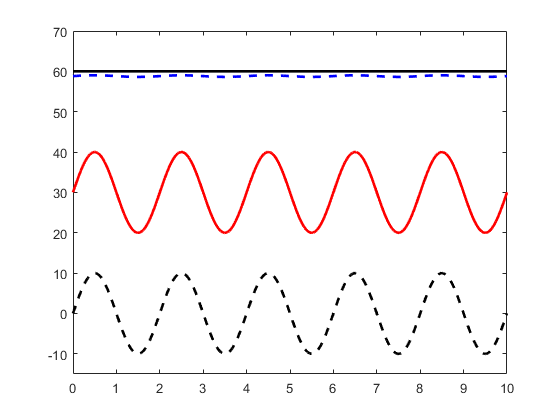

clear all
close all
clc

t  = 0:0.01:10; % time

wr = 60 + 0*t;  % reference speed
d  = 10*sin(pi*t); % disturbance

aModel = 2.0;   % y = aModel*u
aTrue  = 1.0;   % y = aTrue*u

uOL = wr/aModel;     % Open-loop u based on model
yOL = aTrue*uOL + d; % Open-loop response

K   = 50.0;
yCL = aTrue*K/(1+aTrue*K)*wr + d/(1+aTrue*K);

plot(t,wr, 'k', 'linew', 2); hold on;
plot(t,yOL, 'r', 'linew',2);
plot(t,d, 'k--', 'linew',2);
plot(t,yCL, 'b--', 'linew',2);
ylim([-15 70]);